# DC Motor Position with Fuzzy Logic Control

This tutorial demonstrates DC Motor position control using a fuzzy controller created with the Fuzzy Logic Toolbox, covering motor dynamics, PI control simulation parameters, fuzzy position controller design, and controller comparisons. 

## 1. Defining the DC Motor Dynamics

Electrical modeling of a DC motor focuses on the circuit elements, capturing voltage, current, and resistance relationships. Meanwhile, mechanical modeling delves into the motor's dynamics, encompassing torque, friction, and inertia to predict rotational motion and behavior.

####  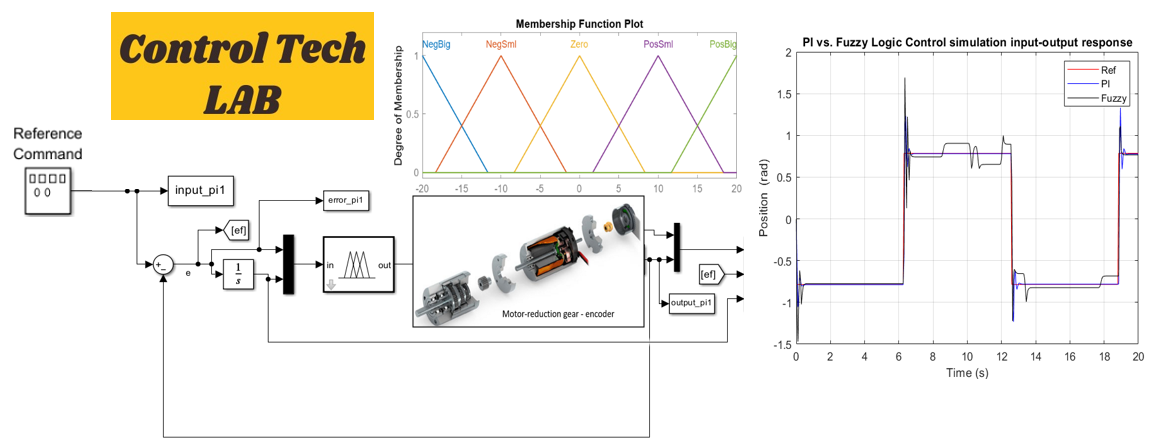

#### Dynamics

 A DC motor can be defined using a 2nd order transfer function of the form below:


$$\Gamma = KV = J\ddot{\theta} + v\dot{\theta} + \tau^{nlf}

$$


$\Gamma
$: Motor torque.

$K
$: Motor constant.

$v$: Viscous friction.

$J
$: Motor inertia.

$\tau^{nlf}
$: Static Coulomb friction.

$V$: Input (voltage).

#### **The Laplace transform**

Upon applying the Laplace transform to the differential equation, we obtain its representation in the s-domain.


$$KV(s) = Js^2\theta(s) + v\theta(s)
$$


Then using this equation we obtain this transfer function:


$$ \frac{\theta(s)}{V(s)}= \frac{\frac{k}{J}}{s(s + \frac{v}{J})}
$$
 
$$= \frac{A}{s(s + B)}
$$


Where the main motor parameters will be:


$$A=\frac{k}{J}$$
 
$$B=\frac{v}{J}$$


Defining system as transfer function to control the motor's speed 


$$G(s) =\frac{\dot{\theta}(s)}{V(s)} = \frac{A}{s+B}
$$


#### Motor parameters 

DC motor parameters which have been previously experimentaly estimated and saved. You can now load the A and B parameters 

clc;clear; close all;
load('estimated_AB.mat');

We obtain the following transfer function:

num=A;
den=[1 B];
sys=tf(num,den)

sys =
 
    208.2
  ---------
  s + 20.42
 
Continuous-time transfer function.
Model Properties


## 2. DC Motor Position Control Using PI Control

PI controller of the form is used to :

#### 
$$C(s) = K_P + \frac{K_I}{s} = K_P\left(1 + \frac{1}{T_Is}\right)
$$


Where $K_p
$ is the proportional gain and $K_i$ is the integral gain, $T_i=\frac{K_p}{K_i}$ is the integral time constant.

#### Simulation prameters

Ts=0.05; 
Tf=20;
Ref=pi/4;
freq=0.5;

#### Creating a reference PI controller

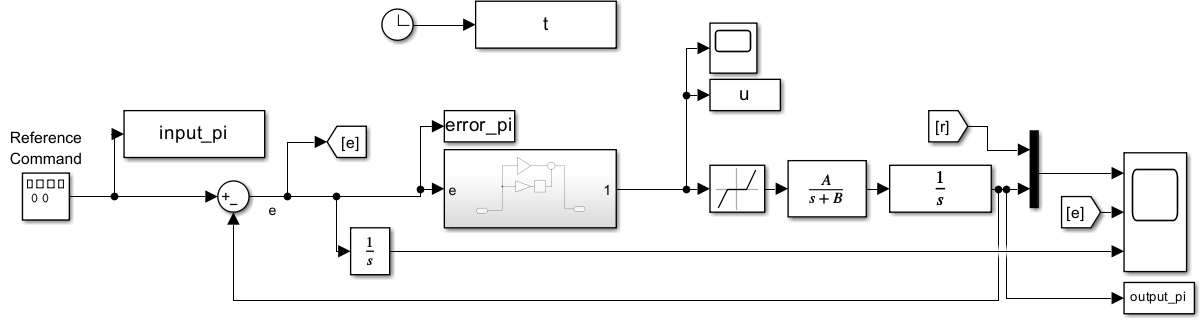

The designed Fuzzy Controller will be compared to a conventional PI controller. The corresponding PI controller parameters are selected as

Kp=5.0;
Ki=0.025;

## 3. Fuzzy Position Controller Design

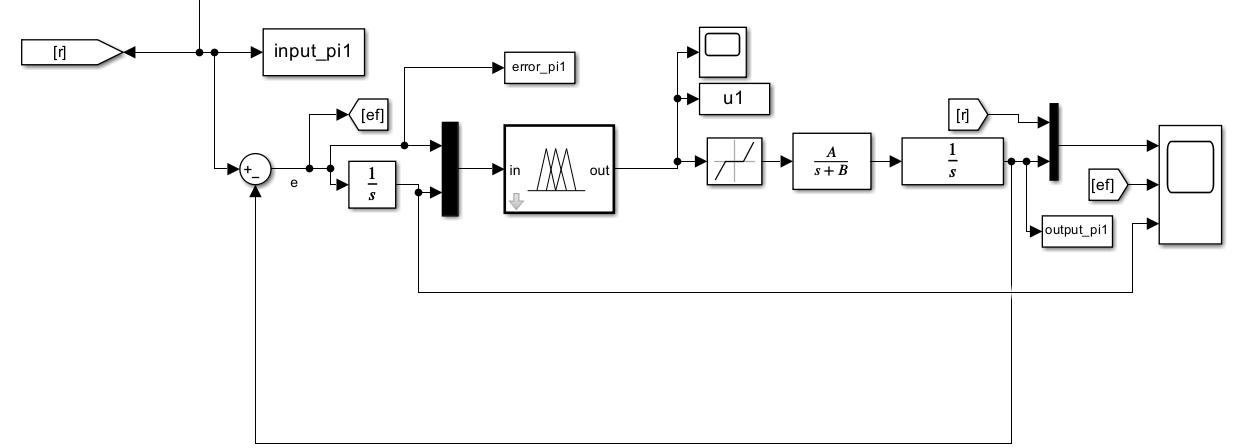

A Mamdani-type Fuzzy Controller is to be designed for current problem. While doing that, choices for the number of membership functions (MFs) for each input and output, their shapes and ranges, the rule base, the defuzzification method and the prescale factor and postscale factor are very important. For the sake of this simple application, some standard choices for these are to be made.

As a result, 3 MFs for the error input, 5 MFs for the error integral input and 5 MFs for the control signal output are chosen. Shapes and ranges for said MFs are as below.

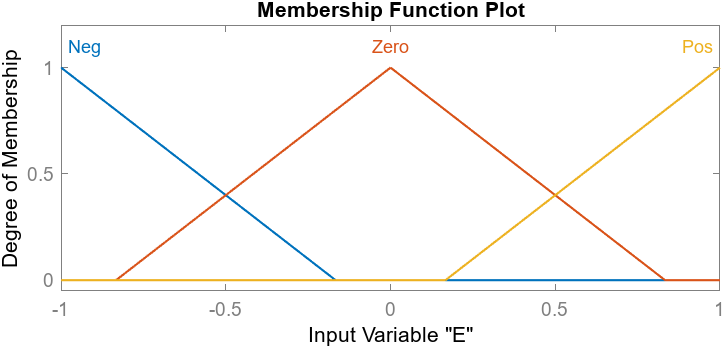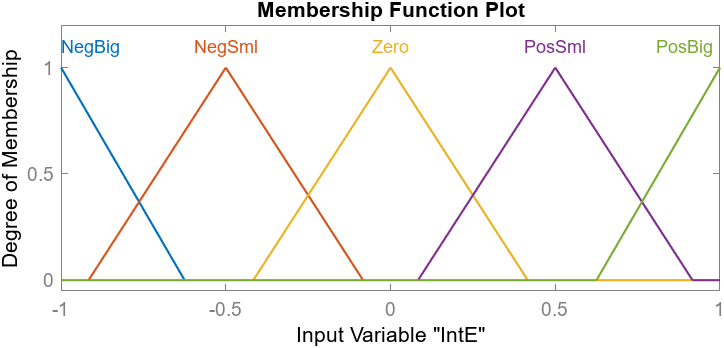

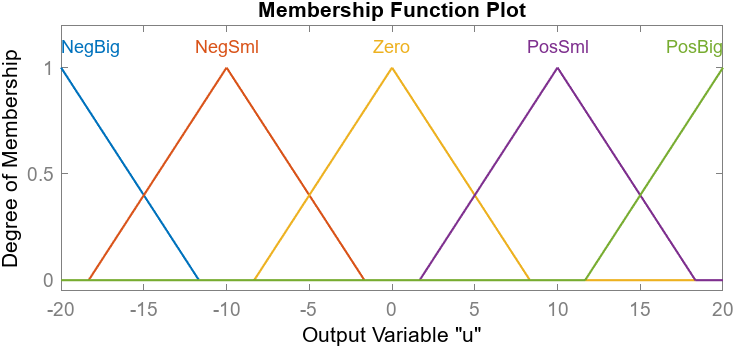

The rule base along with a centroid defuzzification method result with the following control surface.

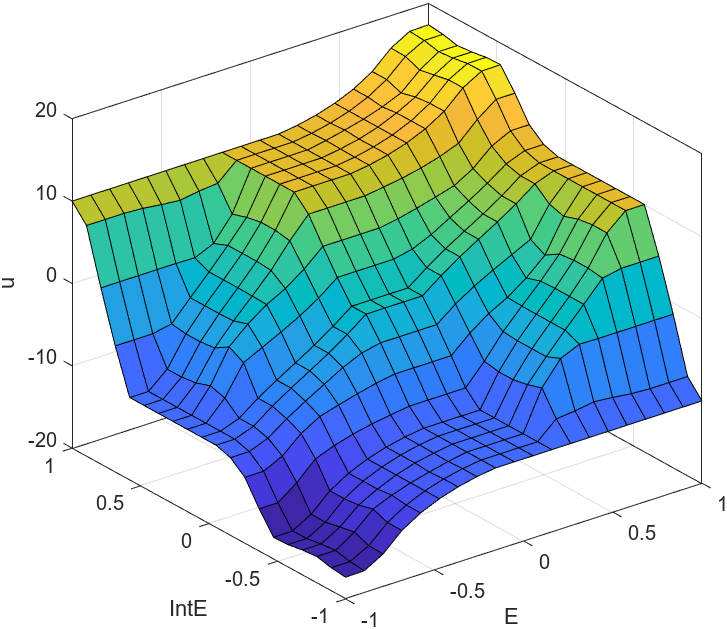

The fuzzy system is designed using Fuzzy Logic Designer and saved in "DCVelMamdani3.fis". It can be loaded as below.

warning('off','all')
warning

All warnings have the state 'off'.


fis = readfis('DCVelMamdani3.fis');
sim DC_pos_22.slx ;
warning('off','all')
warning

All warnings have the state 'off'.


## 4. Comparing Controllers

The designed position fuzzy logic controller is tested and compared to the PI controller using Simulink  

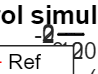

figure (1);
plot(t,input_pi,'r',t,output_pi,'b',t,output_pi1,'k');grid on;
xlabel('Time (s)');
ylabel('Position  (rad)');
title('PI vs. Fuzzy Logic Control simulation input-output response');
legend('Ref', 'PI', 'Fuzzy');

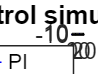


figure (2);
plot(t,u,'b',t,u1,'k');grid on;
xlabel('Time (s)');
ylabel('Control signal (V)');
title('PI vs. Fuzzy Control simulation - control signal');
legend('PI', 'Fuzzy');

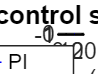

figure (3);
plot(t,error_pi,'b',t,error_pi1,'k');grid on;
xlabel('Time (s)');
ylabel('Position Error (rad)');
title('PI vs. Fuzzy control simulation - error');
legend('PI', 'Fuzzy');